Examen 2021 parte no lineales

## Apartado a)

syms x [1 2] real
system(1, 1) = x(2);
system(2, 1) = -x(1)^3 + x(1) - x(2);

system

$$system = \left(\begin{array}{c} x_{2}\\ -{x_{1}}^{3}+x_{1}-x_{2} \end{array}\right)$$

%Busco los puntos de equilibrio
xeq = solve(system, x)

xeq = struct with fields:
    x1: [3×1 sym]
    x2: [3×1 sym]


xeq = [xeq.x1'; xeq.x2']

$$xeq = \left(\begin{array}{ccc} 0 & -1 & 1\\ 0 & 0 & 0 \end{array}\right)$$

%Linealizar: saco el jacobiano
J = jacobian(system)

$$J = \left(\begin{array}{cc} 0 & 1\\ 1-3\,{x_{1}}^{2} & -1 \end{array}\right)$$

%Ahora evalúo el jacobiano en cada punto de equilibrio y luego saco los
%autovalores.

J0 = subs(J, x, xeq(:, 1)');
J1 = subs(J, x, xeq(:, 2)');
Jn1 = subs(J, x, xeq(:, 3)');

%Saco los autovalores
Eigen0 = eig(J0) %Para 0 0

$$Eigen0 = \left(\begin{array}{c} -\frac{\sqrt{5}}{2}-\frac{1}{2}\\ \frac{\sqrt{5}}{2}-\frac{1}{2} \end{array}\right)$$

Un autovalor tiene parte real positiva y otro negativa, esto significa que es estable en x1 e inestable en x2, luego es un punto de silla. 

Eigen1 = eig(J1) %Para 1 0

$$Eigen1 = \left(\begin{array}{c} -\frac{1}{2}-\frac{\sqrt{7}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2} \end{array}\right)$$

Ambos tienen parte real negativa, luego es un punto estable. 

Eigenn1 = eig(Jn1) %Para -1 0

$$Eigenn1 = \left(\begin{array}{c} -\frac{1}{2}-\frac{\sqrt{7}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2} \end{array}\right)$$

Lo mismo que en le otro apartado, es un punto estable también. 

## Apartado b)

%syms z [1, 2] real
V = 1/4*x(1)^4 - 1/2*x(1)^2 + 1/2*x(2)^2 + 1/4 

$$V = \frac{{x_{1}}^{4}}{4}-\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}+\frac{1}{4}$$

V10 = subs(V, x, xeq(:, 2)') %para 1 0

$$V10 = 0$$

Vn10 = subs(V, x, xeq(:, 3)') %para -1 0 

$$Vn10 = 0$$

Hemos comprobado que la función de Lyapunov es 0 en los puntos de equilibrio a analizar. 

Ahora vamos con la derivada de Lie. 

Vlie1 = simplify(gradient(V)' * system)

$$Vlie1 = -{x_{2}}^{2}$$

Que es una función semidefinida negativa, siendo solo 0 si x2 = 0. Por consiguiente, para (x1, 0) puede pasar cualquier cosa, pero toda solución con x2 != 0 convergerá a la recta x2 = 0. 

Si miramos las ecuaciones sin más, para el caso de x2 = 0,

x1' = 0

x2' = x1^3 - x1

Los puntos de equilibrio necesitan que x2' sea 0 también, de modo que x1 = -1 o 1 solamente. Esto nos deja que solo hay tres puntos de equilibrio, que son los obtenidos anteriormente. 

## Apartado c)

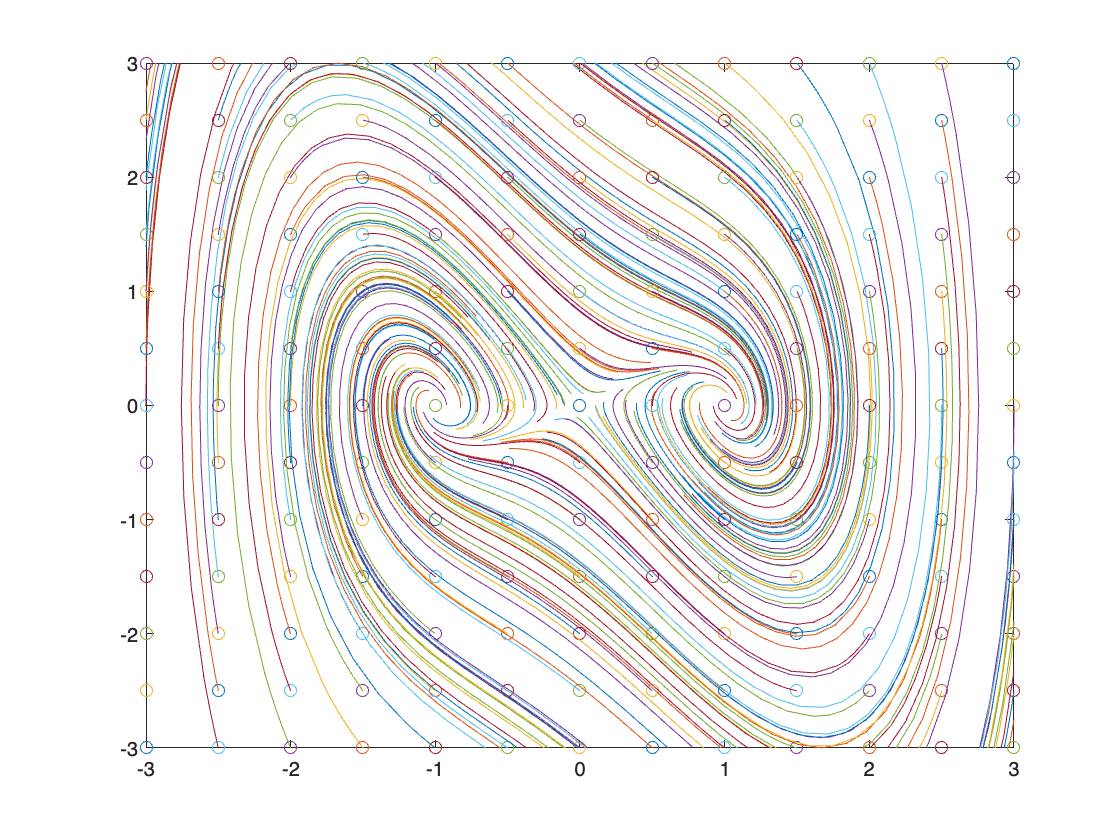

for i = -3:0.5:3
    for j = -3:0.5:3
        [t, x] = ode45(@(t, x)sys(t, x), [0 3], [i; j]);
        plot(i, j, "o"), hold on;
        plot(x(:, 1), x(:, 2));
        xlim([-3 3])
        ylim([-3 3])
    end
end

Si tomamos una energía total $E_p+E_c \leq \frac{1}{4}$

Tendríamos que ,


$$ \frac{1}{4}x_1^4-\frac{1}{2}x_1^2+\frac{1}{2}x_2^2 \leq 0$$


Podemos despejar la cinetica en función de la potencial,


$$x_2 = \pm \sqrt{ \frac{1}{2}x_1^2-\frac{1}{4}x_1^4} = \pm \frac{x_1}{2} \sqrt{ 2-x_1^2}$$


Lo que de paso nos marca el límite para la posición $-\sqrt{2}\leq x_1 < 0$ para el punto $-1$ y $0 < x_1 \leq \sqrt{2}$ para el punto 1.

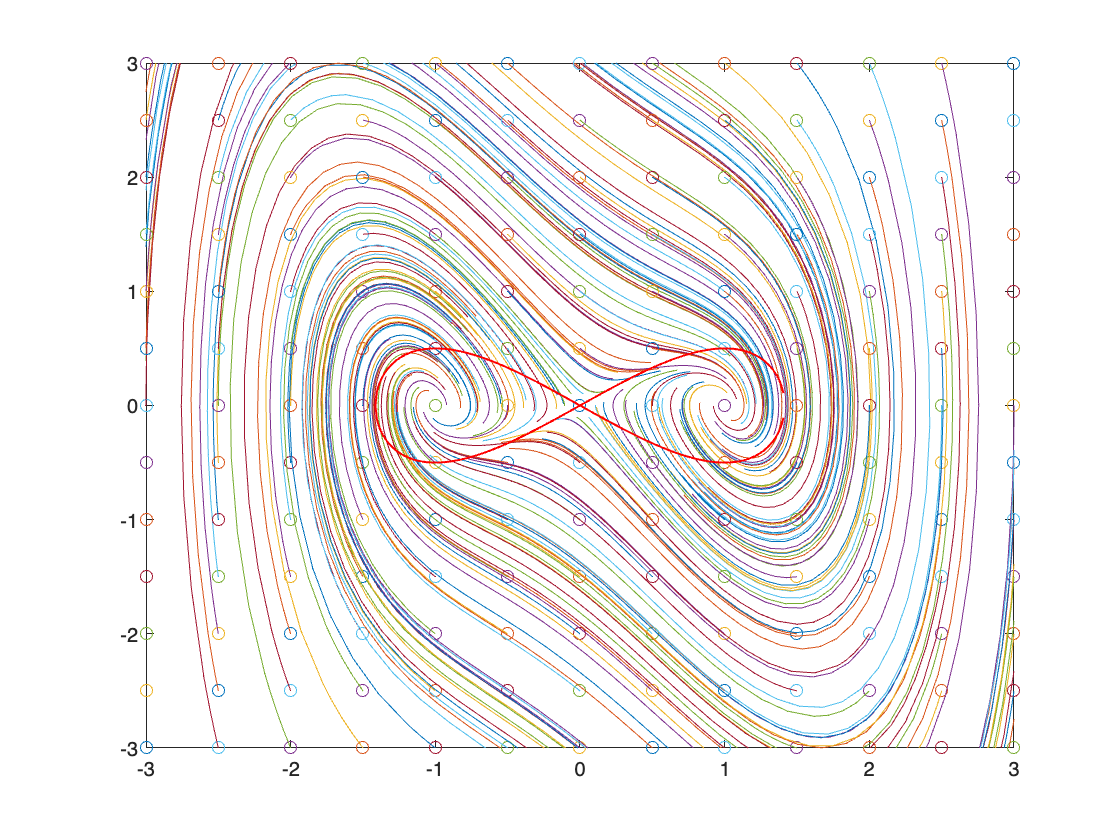

x=-sqrt(2):0.01:sqrt(2);
yp = x.*sqrt(2-x.^2)/2;
yn = -yp;
plot(x,yp,'r',"LineWidth",1)
plot(x,yn,'r',"LineWidth",1); hold off;

function ydot = sys(t, y)
    ydot(1, 1) = y(2, 1);
    ydot(2, 1) = -y(2, 1) - y(1, 1)^3 + y(1, 1);
end